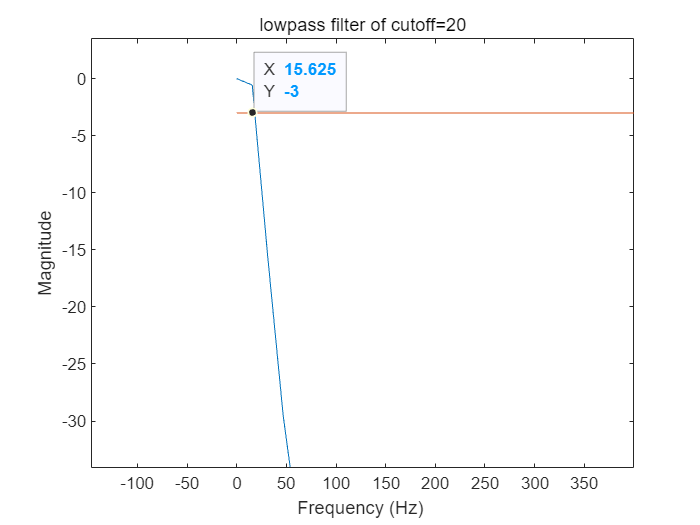

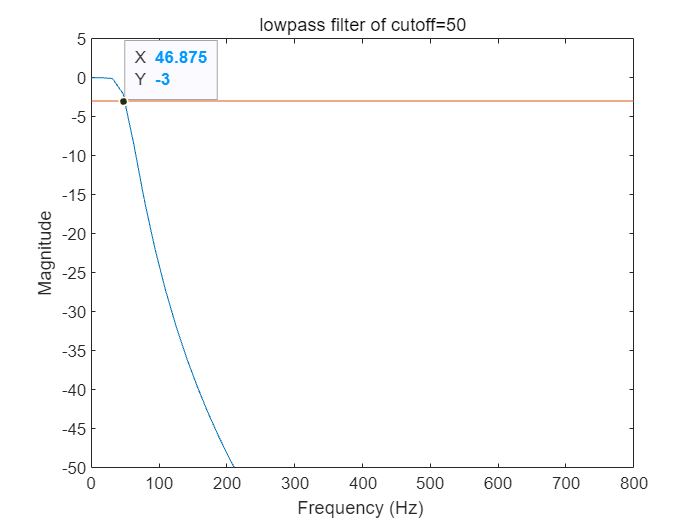

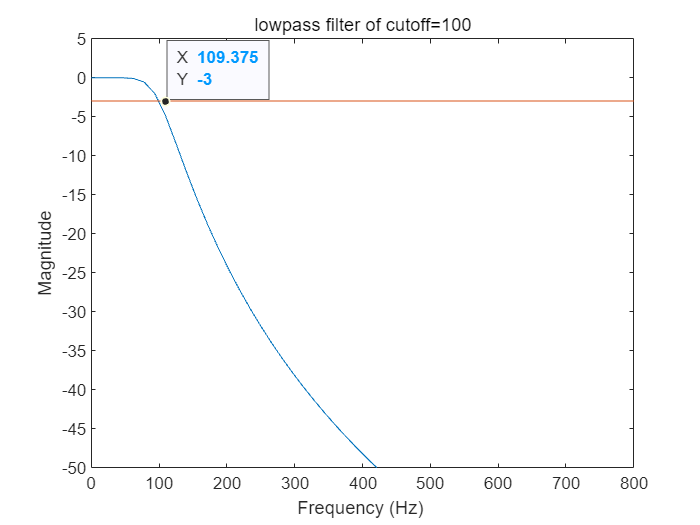

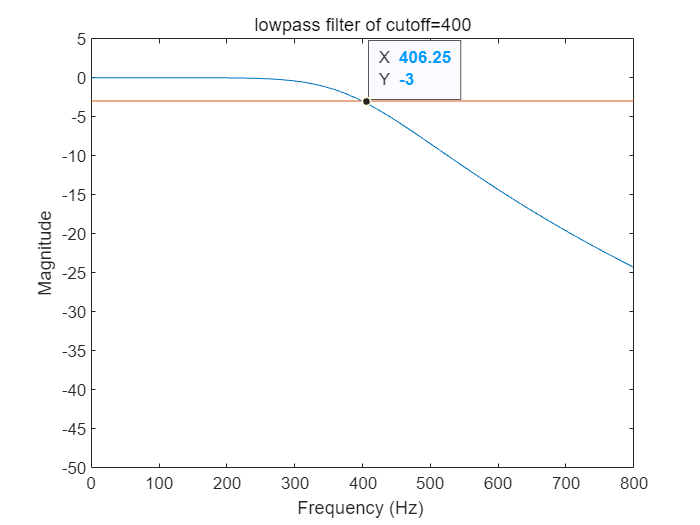

%% 低通滤波器验证
clear; clc; close all;
[x, fs] = audioread ("C_01_02.wav");
but_order = 4;
for ctof_fq = [20 50 100 400]
    [lpf_b, lpf_a] = butter(but_order, ctof_fq/(fs/2));
    [h,f]=freqz(lpf_b,lpf_a,512,fs); % Digital filter frequency response
    figure;
    plot(f,20*log10(abs(h))); % in dB scale
    hold on;
    plot(f, ones(1, length(f)).*(-3));
    axis([0 800 -50 5]);
    xlabel('Frequency (Hz) ');
    ylabel('Magnitude');
    title(sprintf("lowpass filter of cutoff=%d", ctof_fq))
end

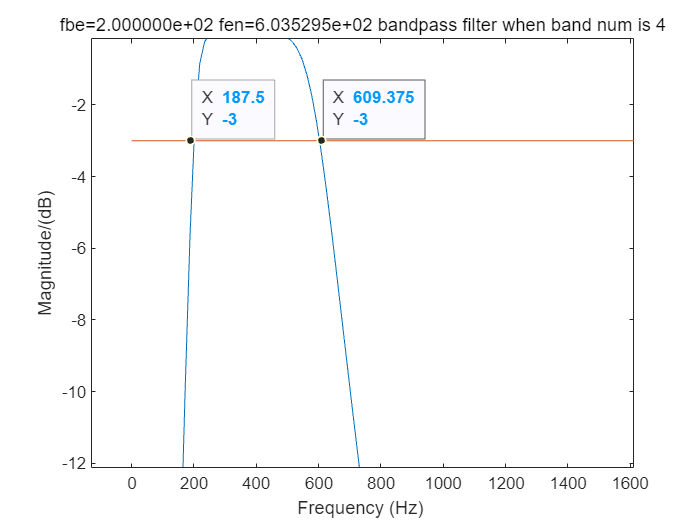

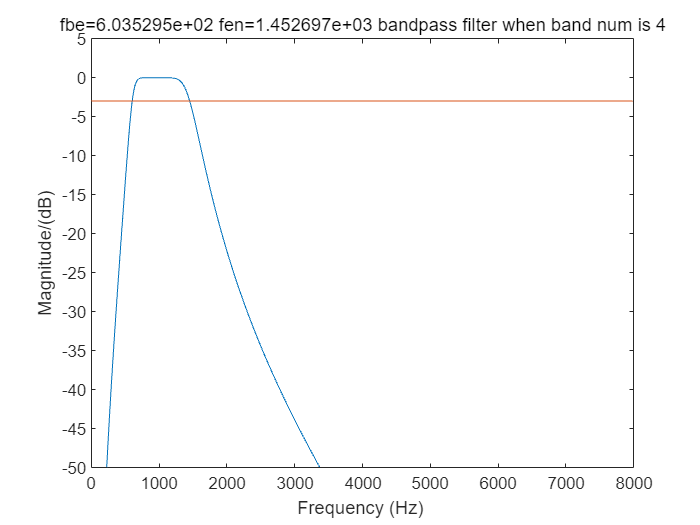

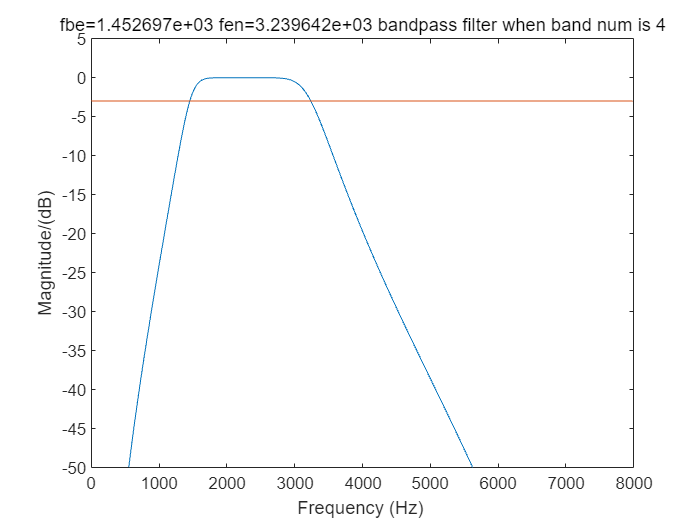

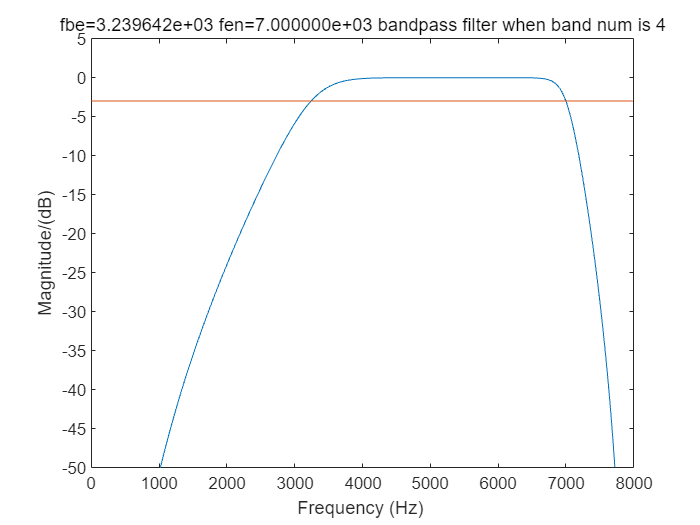

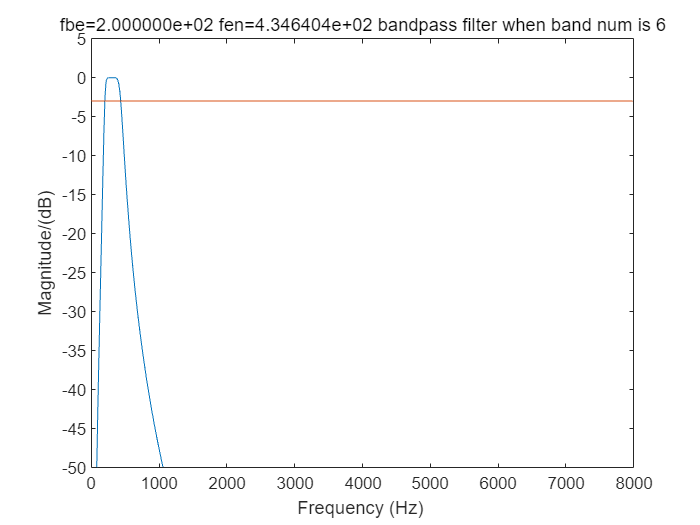

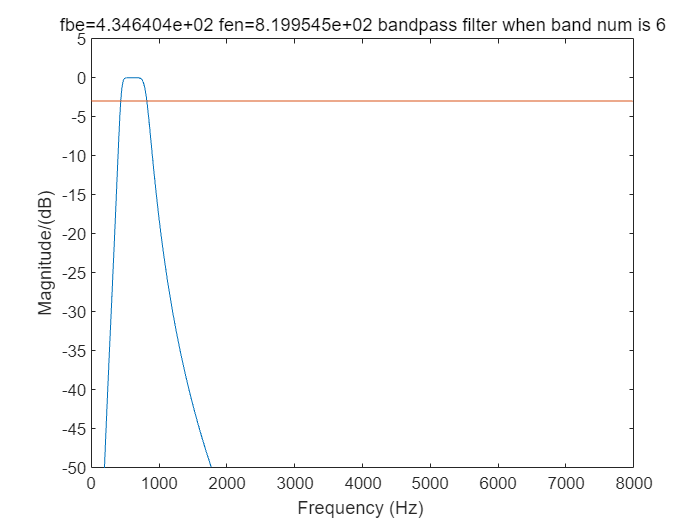

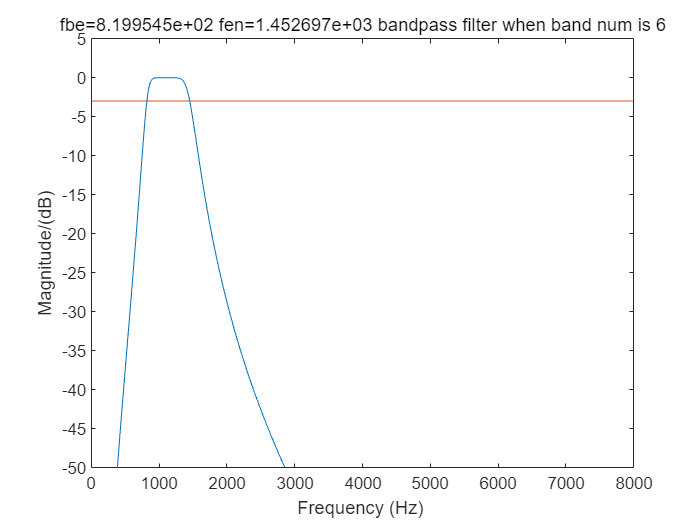

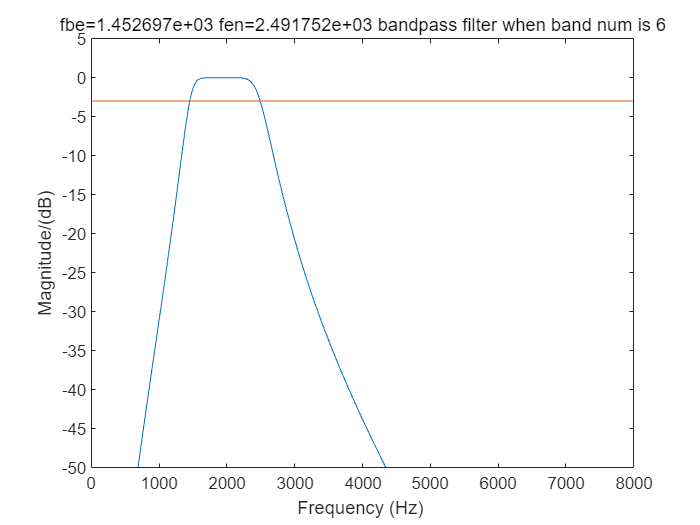


%% 带通滤波器验证
clear; clc; close all;
[sig, fs] = audioread ("C_01_02.wav");
ctof_fq = 50;
but_order = 4;
fbe = 200;
fen = 7000;
for n_bands =  [4 6 8 16]
    f2d = @(f) log10(f/165.4 + 1) / 0.06;
    % 求耳蜗长度
    d2f = @(d) 165.4 * (10.^(0.06*d) - 1);
    % 求对应长度所对应的频率
       
    dbe = f2d(fbe); 
    % 耳蜗长度最小值
    den = f2d(fen);
    % 耳蜗长度最大值
    ds = linspace(dbe, den, n_bands+1);
    % 用n+1个数产生n个间隔，产生耳蜗长度的等间距分布
    
    % cotf_fq是产生包络的截止频率
    t = (0:length(sig)-1)/fs;
    for i = 1:n_bands
        d0 = ds(i); d1 = ds(i+1); 
        % 该滤波器所对应的耳蜗长度
        f0 = d2f(d0); f1 = d2f(d1);
        % 该耳蜗长度对应的频率分布
        [bpf_b, bpf_a] = butter(but_order, [f0 f1]/(fs/2));
        [h,f]=freqz(bpf_b,bpf_a,512,fs); % Digital filter frequency response
        
        thres = ones(1, length(f)).*(-3);
        db_mag = 20*log10(abs(h));
        
        figure;
        plot(f,db_mag); % in dB scale
        hold on;
        plot(f, thres);
        
        axis([0 8000 -50 5]);
        xlabel('Frequency (Hz) ');
        ylabel('Magnitude/(dB)');
        title(sprintf("fbe=%d fen=%d bandpass filter when band num is %d", f0, f1, n_bands))
    end
end